% multipath FIR filter
h_mp = [1 0 .9 0 0 .5 0 0 0 0 .2];
n = 100

n = 100

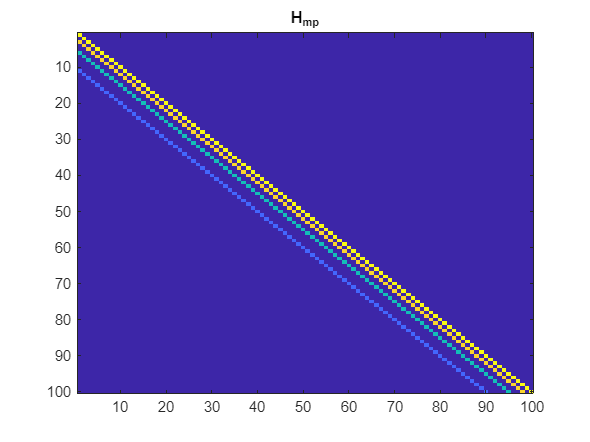


H_mp = lower_shifted_matrix_square(h_mp,n);
figure; imagesc(H_mp)
title('H_{mp}')

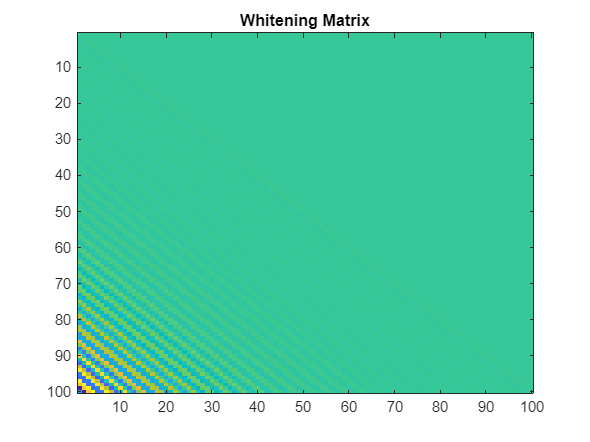

H_w = H_mp^(-.5);
figure; imagesc(H_w)
title('Whitening Matrix')

% H_t = eye(n)
function M = main_and_sub_diag(n)
    M = eye(n);                 % Main diagonal
    M = M + diag(ones(n-1,1), -1); % Subdiagonal below main
end
H_t = main_and_sub_diag(n);
H = H_w * H_t;

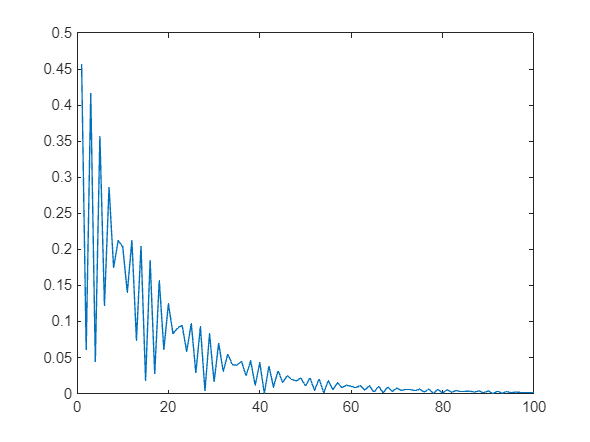

[V,D] = eig(H'*H);
[~,idx] = max(diag(D));
figure; plot(abs(V(:,idx)))

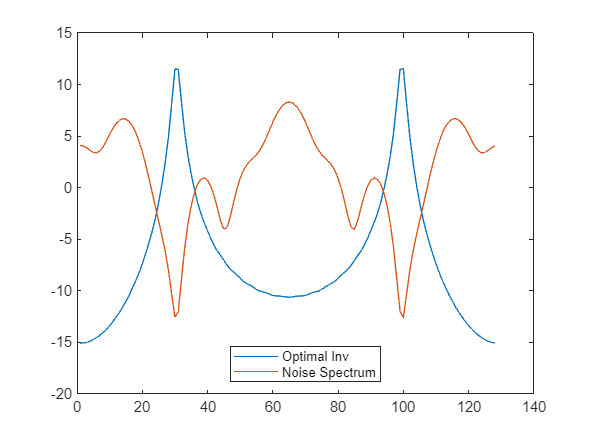

nfft = 128;
figure;
plot(mag2db(abs(fftshift(fft(V(:,idx),nfft)))),'DisplayName','Optimal Inv')
hold on;
plot(mag2db(abs(fftshift(fft(h_mp,nfft)))),'DisplayName','Noise Spectrum')
legend('Location','south')

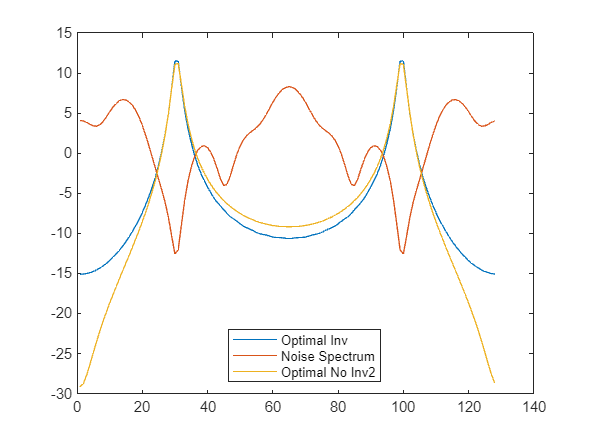

% Verifying the optimal is also the min eigenvector of the uninverted cov
% matrix
[V_min,D_min] = eig(H_mp'*H_mp);
[~,idx] = min(diag(D_min));
% figure; plot(abs(V_min(:,idx)))
plot(mag2db(abs(fftshift(fft(V_min(:,idx),nfft)))),'DisplayName','Optimal No Inv2')

if n == 100
    lfm = phased.LinearFMWaveform('SweepBandwidth',1e5,...
        'OutputFormat','Pulses','SampleRate',1e5,'SweepInterval','Symmetric',...
        'PulseWidth',500e-6,'PRF',10e2,'NumPulses',1);
    tb = lfm.PulseWidth*lfm.bandwidth
    lfm_array = .2*lfm();
else
    lfm = phased.LinearFMWaveform('SweepBandwidth',1e5,...
        'OutputFormat','Pulses','SampleRate',2.2e5,'SweepInterval','Symmetric',...
        'PulseWidth',5e-5,'PRF',2e4,'NumPulses',1);
    tb = lfm.PulseWidth*lfm.bandwidth
    lfm_array = .2*lfm();
    len = length(lfm_array)
end

tb = 50

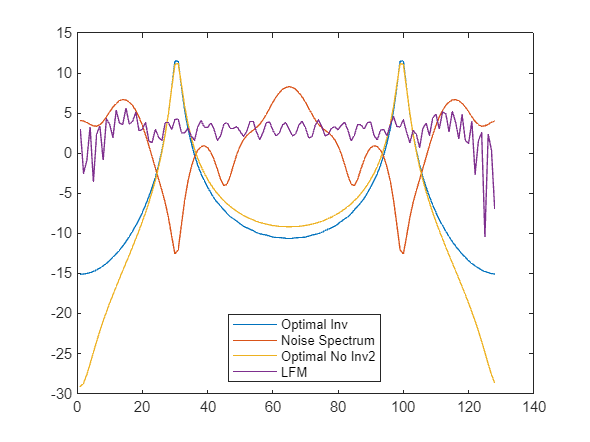

plot(mag2db(abs(fftshift(fft(lfm_array,nfft)))),'DisplayName','LFM')

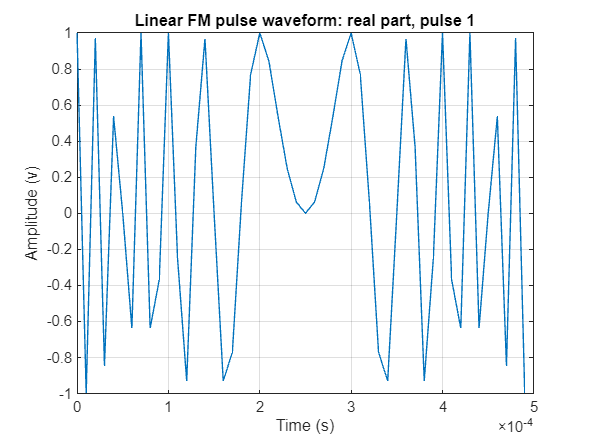

figure; plot(lfm)

% Helpers

function S = lower_shifted_matrix_square(v, N)
    % Ensure v is a column vector
    v = v(:);
    len_v = length(v);
    S = zeros(N,N); % Preallocate output

    for j = 1:N
        % Number of elements from v that can fit in this column
        num_to_copy = min(len_v, N-j+1);
        if num_to_copy > 0
            S(j:j+num_to_copy-1, j) = v(1:num_to_copy);
        end
    end
end